# ParTI Analysis on Bulk SCLC Cell Lines (RNAseq)

clear all 
nArchetypes = 5;

global ForceNArchetypes; ForceNArchetypes = nArchetypes;

% % Instead of setting this at the beginning of the code, I am going to run a
% % for loop later to iterate over different values and these will be
% % reset.
% random_int = randi(1000000)
% outputFileName = sprintf('%d',random_int)
% algNum = 5
% dim = 12
% binSize = 0.1 


% Load the data into Matlab from a comma separated value (CSV) file
% The file is a purely numerical matrix, with patients as rows and genes as
% columns
inputPath = '/Users/smgroves/Documents/Github/Groves-CellSys2021/data/bulk-rna-seq/parti-input/'

inputPath = '/Users/smgroves/Documents/Github/Groves-CellSys2021/data/bulk-rna-seq/parti-input/'

origPath = pwd

origPath = '/Users/smgroves/Documents/GitHub/Groves-CellSys2021/ParTI'

geneExpression = dlmread(strcat(inputPath,'SCLC_combined_Minna_CCLE_batch_corrected_wo_lowgenes_wo_geneNames.csv'), ',');
geneExpression = geneExpression'

geneExpression =     1.8911    2.2081    0.1015    0.0037    1.6013    4.8521    7.0399   -0.0258    0.0113    2.1331    5.3307    2.3353    2.8772    6.0207    0.3653    4.0586    1.4510    6.7046    2.3492    4.5739    2.8431    4.7608    2.3337    4.6397    2.7393    5.3438    0.4148    0.7092    1.5539    0.6724    4.6421    5.2786   -0.0039    3.8389    0.0367    4.1713    0.0075    0.0577    5.6652    3.9951    1.7197    0.1762    3.6810    4.2828    3.5966    3.5047    1.1798    2.2214    0.1739    1.9588
    4.5241    0.3219   -0.1271    0.0075    4.7160    5.3151    4.0385    0.0174    0.0797    2.4834    5.2869    3.2525    5.3915    6.2376    0.0118    5.0199    0.0513    5.6866    2.9079    4.6661    2.3903    5.1188    1.8374    5.4264    3.0978    0.9210    0.0064    3.7290    0.1239    0.2752    3.7920    2.6111    0.6582    7.6518    2.0519    3.4680    0.8473    1.9919   -0.0931    3.5893   -0.1144   -0.0264    4.7655    4.1951    3.8247    2.6423    3.1712    2.8317  

% The file is formated as samples (i.e. patients) x genes. 
% We load gene names.
geneNames = importdata(strcat(inputPath,'geneNames_wo_lowgenes.csv'), ',');

## We import the sample attributes, i.e. the clinical data on patients

These come in two kinds: - discrete attributes, i.e. categorical data (citizenship, gender, cancer progression grade, ...) - continuous attributes, i.e. numerical data (weight, age, tumor volume, ...) We start by loading a file with clinical attributes, both discrete and continuous.

% cd ../../../ParTI/

inputPath = '/Users/smgroves/Documents/Github/Groves-CellSys2021/data/bulk-rna-seq/parti-input/'

inputPath = '/Users/smgroves/Documents/Github/Groves-CellSys2021/data/bulk-rna-seq/parti-input/'


[discrAttrNames, discrAttr] = ...
    read_enriched_csv(strcat(inputPath,'combined_clusters_2020-05-27-MC.csv'), ',');

%where discrAttr is a matrix of patients x attributes. The names of
%the attributes are stored in discrAttrNames.

% Continuous attributes are analysed using a different statistical procedure
% than discrete attributes. We therefore load a file with vectors 'discIdcs' and 
% 'contIdcs' containing the indices of discrete and continuous attributes 
% to be considered in the study:
% load Data/CancerRNAseq/CancerRNAseq_featIdcs.mat;

% We extract continous attributes, discarding the sample ID
% (the order of the clinical records matches that of the expression data)
% contAttrNames = discrAttrNames(:,contIdcs);
% contAttr = discrAttr(:,contIdcs);
% Now we convert contAttr to a matrix of doubles
% contAttr = str2double(contAttr);

% And select the remaining discrete attributes:
% discrAttrNames = discrAttrNames(:,discIdcs);
% discrAttr = discrAttr(:,discIdcs);

## We expand the sample attributes by computing changes in GO category expression

This section is optional. It makes it possible to determine broad gene expression categories that are over-expressed in the vicinity of archetypes. This is helpful to characterize the archetypes.


[GOExpression,GONames,~,GOcat2Genes] = MakeGOMatrix(geneExpression, geneNames, ...
                {'MSigDB/c5.go.bp.v7.2.symbols.gmt'}, ...
                10);
% GOExpression is a matrix of patients x GO categories, and
% GONames contains the name of the GO categories.
% GOcat2Genes is a boolean matrix of genes x GO categories which
% indicates, for each category, which genes were used to compute it.
% In the next line, we expand this matrix so that it has as many columns as
% the number of continuous features (clinical + GO). Because clinical
% features are typically not directly based on specific genes, we add
% zeroes in the corresponding columns:
% GOcat2Genes=[zeros(size(GOcat2Genes,1),size(discrAttr,2)),GOcat2Genes];
% % and we expand the continuous clinical features with GO-based continuous
% % features:
% contAttrNames = [contAttrNames, GONames];
% contAttr = [contAttr, GOExpression];
contAttrNames = GONames;
contAttr = GOExpression;

## Finally, we substitute underscores '_' in variable names with spaces ' '

to prevent the characters following underscores from appearing in indice position.

discrAttrNames = regexprep(discrAttrNames, '_', ' ');
contAttrNames = regexprep(contAttrNames, '_', ' ');


## We are now ready to perform Pareto Task Inference.

We use the PCHA algorithm (5), with up to 8 dimensions. We provide the discrete sample attributes, and ask ParTI to preliminary booleanize these attributes (0). We also pass continuous patient attributes. We pass a boolean matrix specifiying which genes each continuous feature is baesd on (to be used in the leave-one-out procedure). We specify that the enrichment analysis will be performed with a bin size of 5%. Finally, the output of the the analysis will be stored in an Excel spreadsheet, under the name 'CancerRNAseq_enrichmentAnalysis_*.csv'. 5 is PCHA

algNum choses the algorithm to find the simplex: 1 for [Sisal](http://www.lx.it.pt/~bioucas/) (the default), 2 for [MVSA](http://www.lx.it.pt/~bioucas/), 3 for [MVES](http://mx.nthu.edu.tw/~tsunghan/Source%20codes.html), 4 for [SDVMM](http://mx.nthu.edu.tw/~tsunghan/Source%20codes.html), 5 for [PCHA](http://www.mortenmorup.dk/index_files/Page327.htm). If the dataset features a large number of data points, Sisal is recommended. In our experience, a large number of points means at least 10 per dimension (after dimension reduction): 10 points in 1D, 100 points in 2D, 1000 points in 3D, etc.. If a smaller number of data points is provided, MVSA should be preferred.

[arc, arcOrig, pc, coefs1] = ParTI_lite(geneExpression, 5, 12); 


**What are the differences between the different algorithms, what are their pros/cons?**

 - Sisal:  Minimizes the volume of the simplex that encapsulates the data. It is resilient to noise and outliers - data points can end outside of the simplex. Usually archetype are located outside the data. (default)

-  MVSA/MVES:  Minimizes the volume of the simplex that encapsulates the data. It is not resilient to noise and outliers - data points will all be inside the simplex.

- SDVMM: data points are selected as archetypes, maximizing the variance of the data encapsulated within the resulting simplex. By Selecting tolerance radius around the points selected as archetypes, one can expand the simplex. In general, the archetypes are located within the data.

-  PCHA: archetypes are found within the convex hull of the data, maximizing the data encapsulated within the resulting simplex. By selecting a tolerance radius around the points selected as archetypes, one can expand the simplex. In general, the archetypes are located within the data.

For large datasets of thousands data points, the three minimal bounding simplex algorithms (SISAL, MVSA and MVES) give very similar results. We found that the SISAL algorithm performs best since it takes good care of outliers in the dataset and gives the tightest simplex enclosing most of the data points. It is then also natural to use SISAL for calculation of the simplex statistical significance.

However, when the number of data points is on the order of a hundred or less, the SISAL algorithm might ignore important points when calculating the enclosing simplex. This is most relevant when calculating the statistical significance of the simplex. In such cases we used the MVSA algorithm.

% [arc_lite, arcFinal, pc_lite] = ParTI_lite(geneExpression, 5, 60, discrAttrNames, ...
%  discrAttr, 0, contAttrNames, contAttr, [], 0.05, 'c5');
outPath = strcat(origPath, sprintf('/out/%d',nArchetypes))
if ~exist(outPath, 'dir')
    mkdir(outPath);
end
if exist(strcat(outPath, '/arcs_dims.csv'), 'file') == 2
    fprintf('Reloading previously computed archetypes\n');
    load(strcat(outPath, '/arcs_dims.csv'))
    arc = arcs_dims;
    load(strcat(outPath, '/arcsOrig_genes.csv'))
    arcOrig = arcsOrig_genes;
else 
    [arc, arcOrig, pc, coefs1] = ParTI_lite(geneExpression, 5, ForceNArchetypes); 
    %[arc, arcOrig, pc, errs, pval, coefs1] = ParTI(geneExpression);
%     save(strcat(origPath, '/out/arcs_dims.tsv'), 'arc', '-ascii')
    csvwrite(strcat(outPath, '/arcs_dims.csv'), arc)
%     save(strcat(origPath, '/out/arcsOrig_genes.tsv'), 'arcOrig', '-ascii')
    csvwrite(strcat(outPath, '/arcsOrig_genes.csv'), arcOrig)
    %save(strcat(origPath, '/pcsOrig_samplesXdims.tsv'), 'pc', '-ascii')
    csvwrite(strcat(outPath, '/pcsOrig_samplesXdims.csv'), pc)
    %save(strcat(origPath, '/projOrig_varsXdims.tsv'), 'coefs1', '-ascii')
    csvwrite(strcat(outPath, '/projOrig_varsXdims.csv'), coefs1)
%     csvwrite(strcat(origPath, '/out/arcs_errs.csv'), errs)
%     csvwrite(strcat(origPath, '/out/arcs_pval.csv'), pval)
end

clear pc coefs1 errs pval;


## Finally, we perform the compete analysis, including randomization

controls and archetype error estimation.

random_int = randi(1000000);

outputFileName = sprintf('%d',random_int);

algNum = 5;
dim = 12;
binSize = 0.1 ;
% [arc, arcFull, pc, errs, pval, coefs, P, tRatioRand, tRatioReal] = ParTI(geneExpression, algNum, dim, discrAttrNames, ...
%     discrAttr, 0, contAttrNames, contAttr,GOcat2Genes, binSize, strcat(outPath,'/', outputFileName));

% The code above is what is in the early version of the manuscript. We would like to run this in a loop for 4, 5, and 6 archetypes, keeping information about the t-ratio test in each case. 

% Without enrichments

[arc, arcFull, pc, errs, pval, coefs, P, tRatioRand, tRatioReal] = ParTI(geneExpression, algNum, dim, ...
    [],[],0,[],[],[], binSize, strcat(outPath,'/', outputFileName));

Save in params.txt all of the parameters for this run, as well as the associated p value, the randomly generated barcode, and the t-ratio. 

fid = fopen(strcat(origPath,'/params.txt'), 'a+');
fprintf(fid, '%d, %d, %d, %d, %d,%d, %d\n', random_int,algNum,dim,binSize, nArchetypes, pval, tRatioReal);
fclose(fid);
csvwrite(strcat(outPath,sprintf('/%s_arc_full.csv',outputFileName)), arcFull);
csvwrite(strcat(outPath,sprintf('/%s_err.csv',outputFileName)), errs);
csvwrite(strcat(outPath,sprintf('/%s_coefs.csv',outputFileName)), coefs);
csvwrite(strcat(outPath,sprintf('/%s_tRatioRand.csv',outputFileName)), tRatioRand);
clear arc arcFull pc errs pval coefs P tRatioRand tRatioReal


% % Algorithms 2 and 3
% % Didn't finish running
% dim = 12;
% binSize = 0.1 ;
% for nArchetypes = [4 5 6]
%     for algNum = [2 3]
%         ForceNArchetypes = nArchetypes;
%         random_int = randi(1000000);
%         outputFileName = sprintf('%d',random_int);
%         outPath = strcat(origPath, sprintf('/out/%d',nArchetypes));
%         [arc, arcFull, pc, errs, pval, coefs, P, tRatioRand, tRatioReal] = ParTI(geneExpression, algNum, dim, discrAttrNames, ...
%         discrAttr, 0, contAttrNames, contAttr,GOcat2Genes, binSize, strcat(outPath,'/', outputFileName));
%         fid = fopen(strcat(origPath,'/params.txt'), 'a+');
%         fprintf(fid, '%d, %d, %d, %d, %d,%d, %d\n', random_int,algNum,dim,binSize, nArchetypes, pval, tRatioReal);
%         fclose(fid);
%         csvwrite(strcat(outPath,sprintf('/%s_arc_full.csv',outputFileName)), arcFull);
%         csvwrite(strcat(outPath,sprintf('/%s_errs.csv',outputFileName)), errs);
%         csvwrite(strcat(outPath,sprintf('/%s_coefs.csv',outputFileName)), coefs);
%         csvwrite(strcat(outPath,sprintf('/%s_tRatioRand.csv',outputFileName)), tRatioRand);
%     
%         clear arc arcFull pc errs pval coefs P tRatioRand tRatioReal
%     end
% end

Starting to perform PCA, for big data on slow computers this may take a while...
Calculating explained variance with PCHA (Morup M, Hansen KL, 2011)
Warning! ForceNArchetypes preset in workspace to 4. Will now use that value.
Calculating archetypes positions with MVSA (Li J, Bioucas-Dias JM, 2008)
finished finding the archetypes
Now computing t-ratios.
10% done

 something wrong with the line search

 outputing the VCA solution

 something wrong with the line search

 outputing the VCA solution

 something wrong with the line search

 outputing the VCA solution

 something wrong with the line search

 outputing the VCA solution

 something wrong with the line search

 outputing the VCA solution

 something wrong with the line search

 outputing the VCA solution

 something wrong with the line search

 outputing the VCA solution

 something wrong with the line search

 outputing the VCA solution
20% done
30% done
40% done

 something wrong with the line search

 something wrong with the

Finished sorting data points.
Your data was divided into 10 bins.


Finished computing discrete enrichments.
Finished computing continuous enrichments.
Now applying leave-one-out to verify robustness enrichment of GO categories
5% done
10% done
15% done
20% done
25% done
30% done
35% done
40% done
45% done


## Running ParTI in a loop over algorithm, nArchetypes, binSize, and dim

Starting to perform PCA, for big data on slow computers this may take a while...


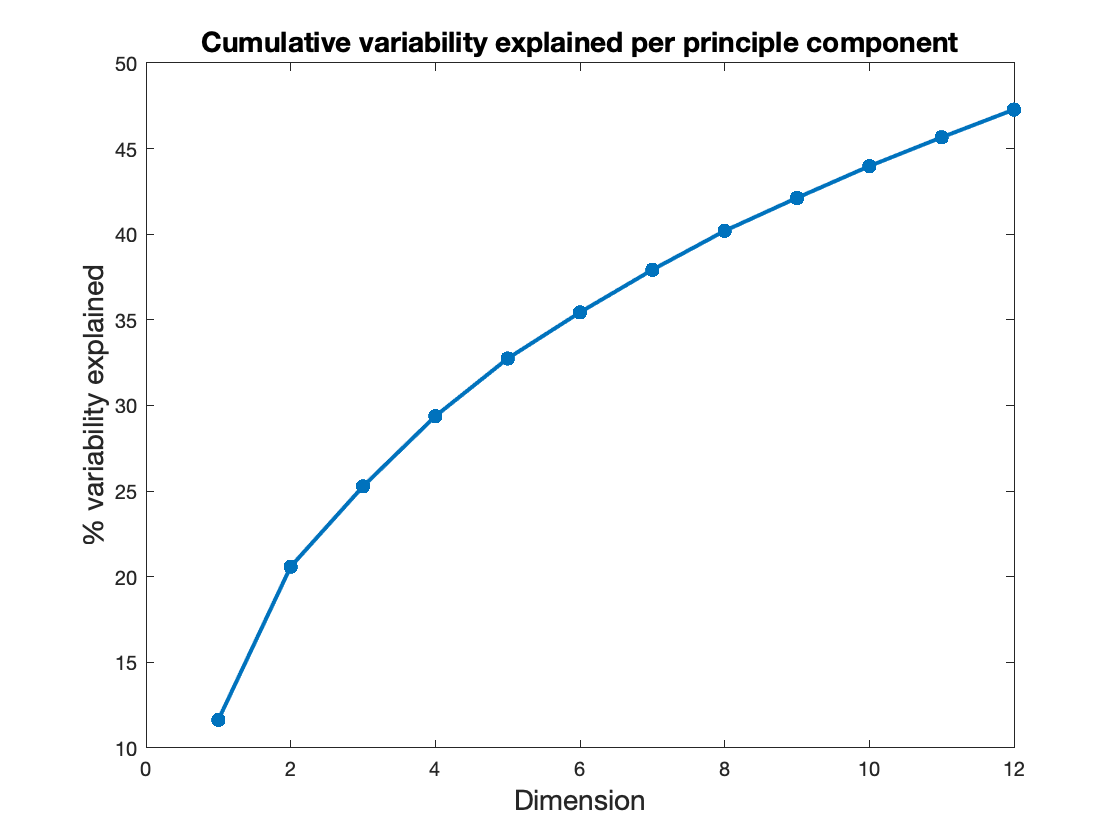

Calculating explained variance with PCHA (Morup M, Hansen KL, 2011)


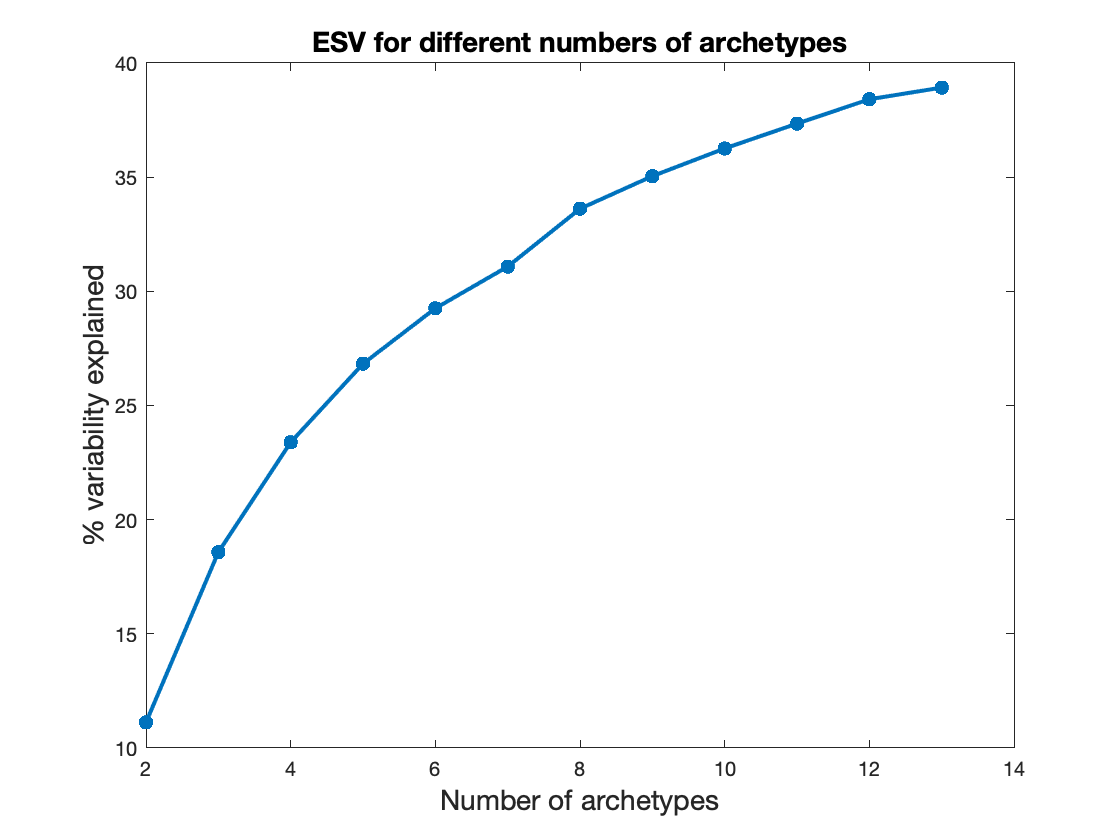

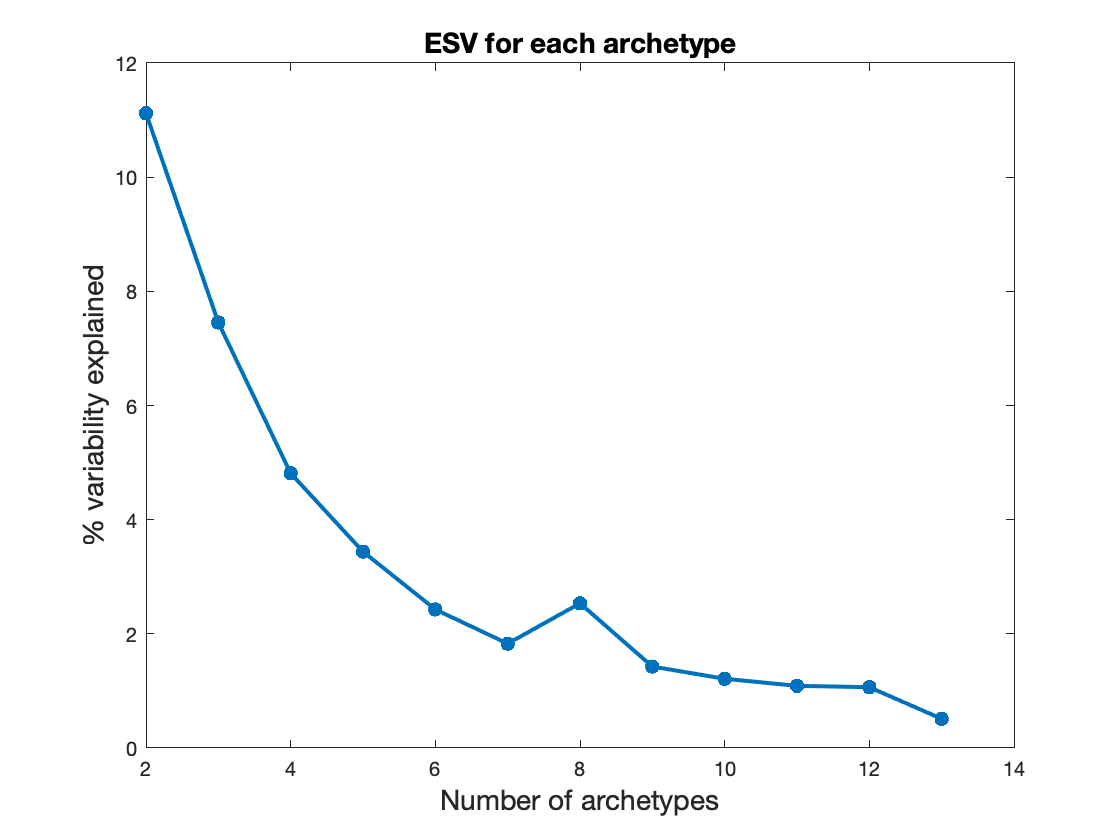

Warning! ForceNArchetypes preset in workspace to 3. Will now use that value.
Calculating archetypes positions with PCHA (Morup M & Hansen LK, 2011)
finished finding the archetypes
Now computing t-ratios.
10% done
20% done
30% done
40% done
50% done
60% done
70% done
80% done
90% done
100% done
The significance of 3 archetypes has p-value of: 0.50800 
Now calculating errors on the archetypes.
10% done
20% done
30% done
40% done
50% done
60% done
70% done
80% done
90% done
100% done
finished finding the archetypes error distribution


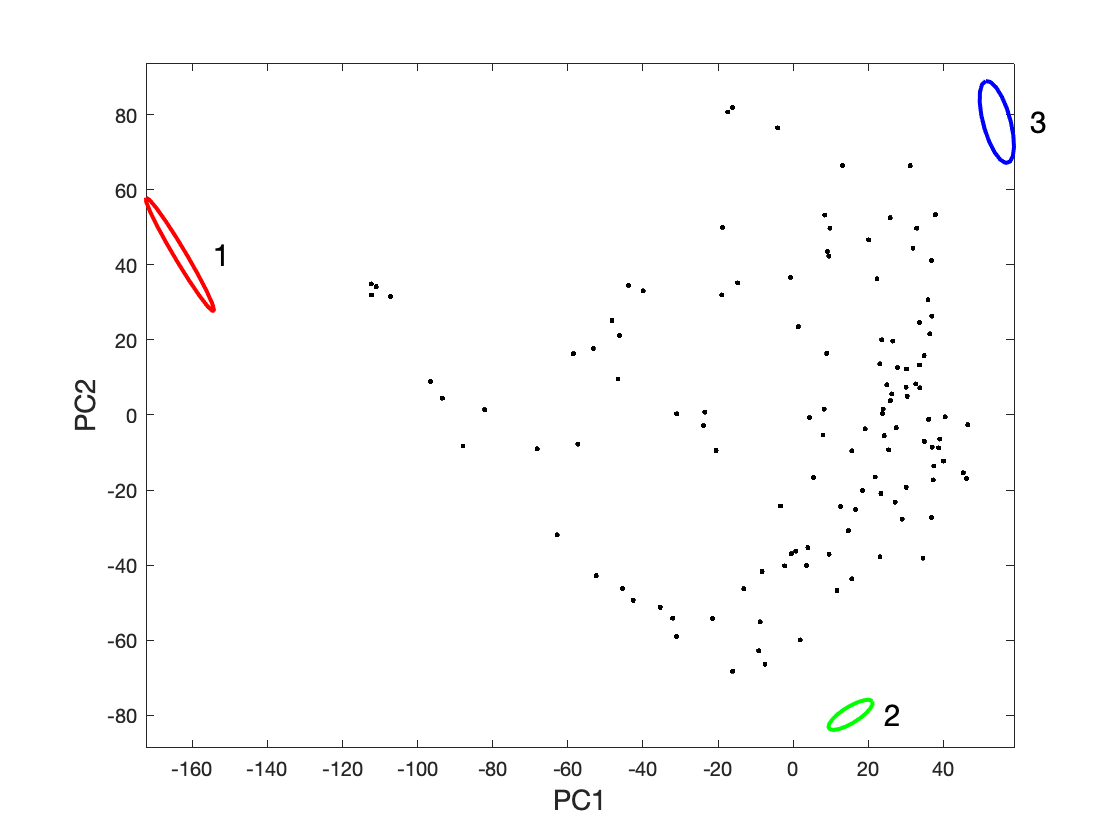

Finished sorting data points.
Your data was divided into 10 bins.


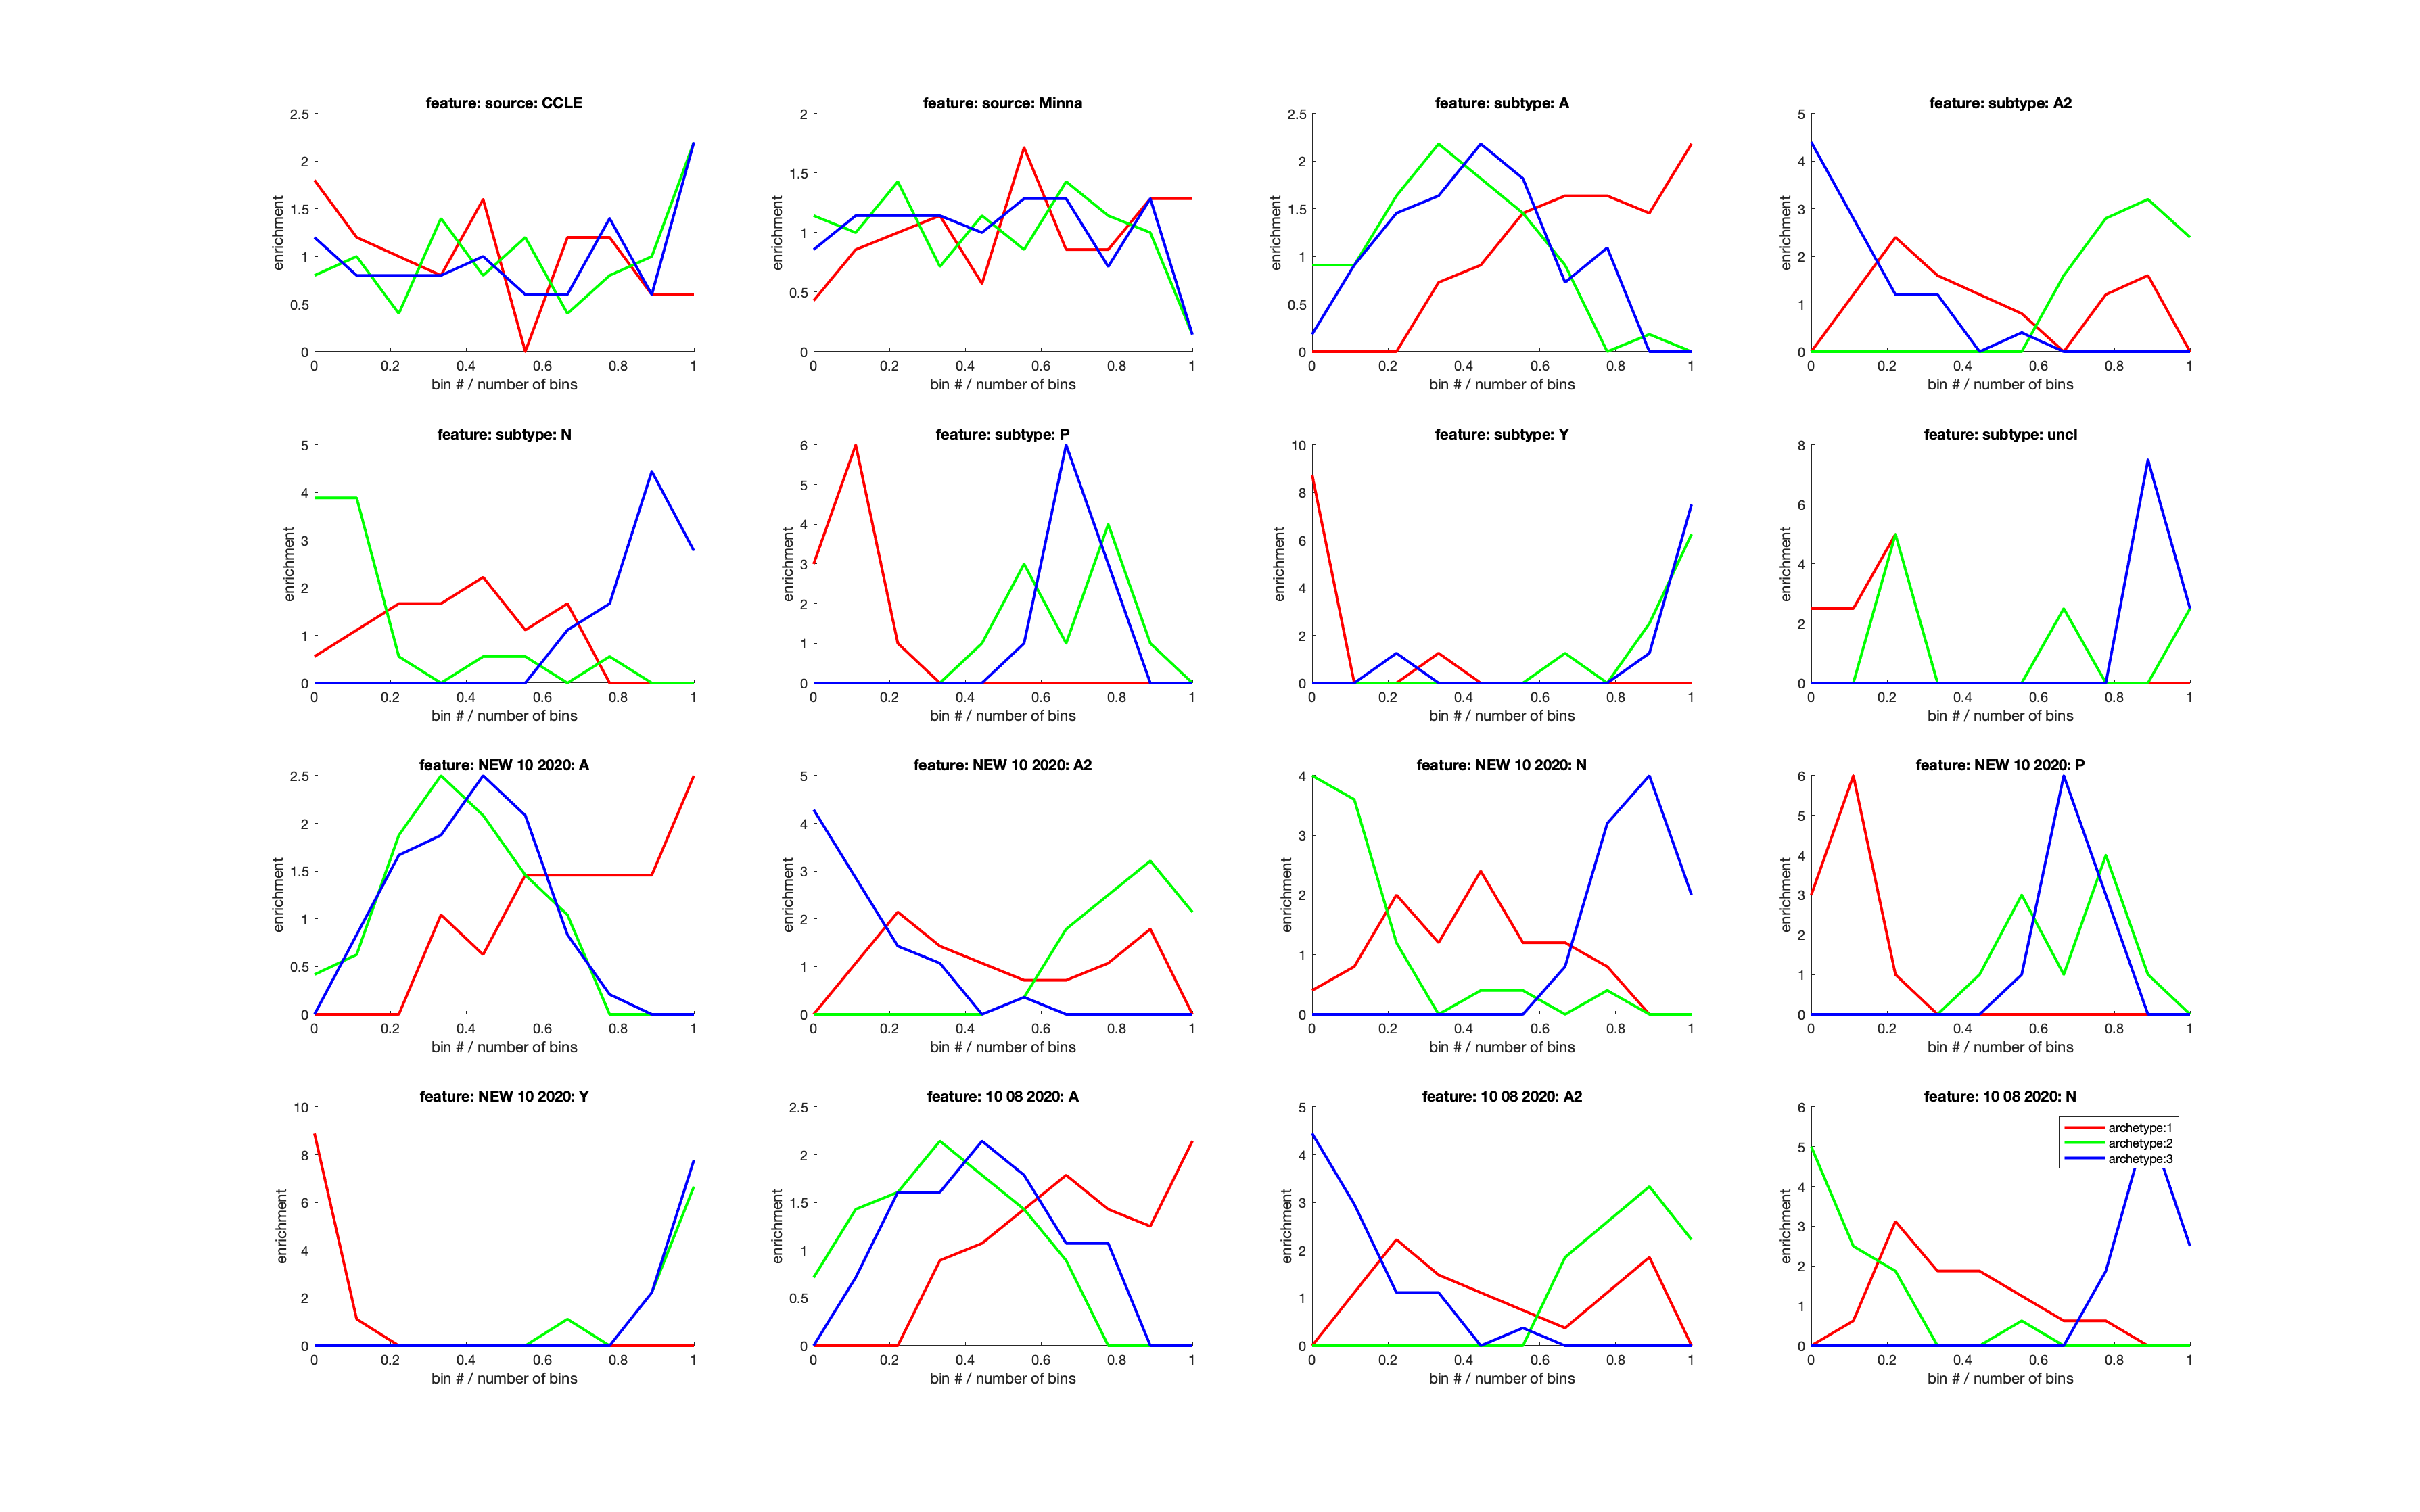

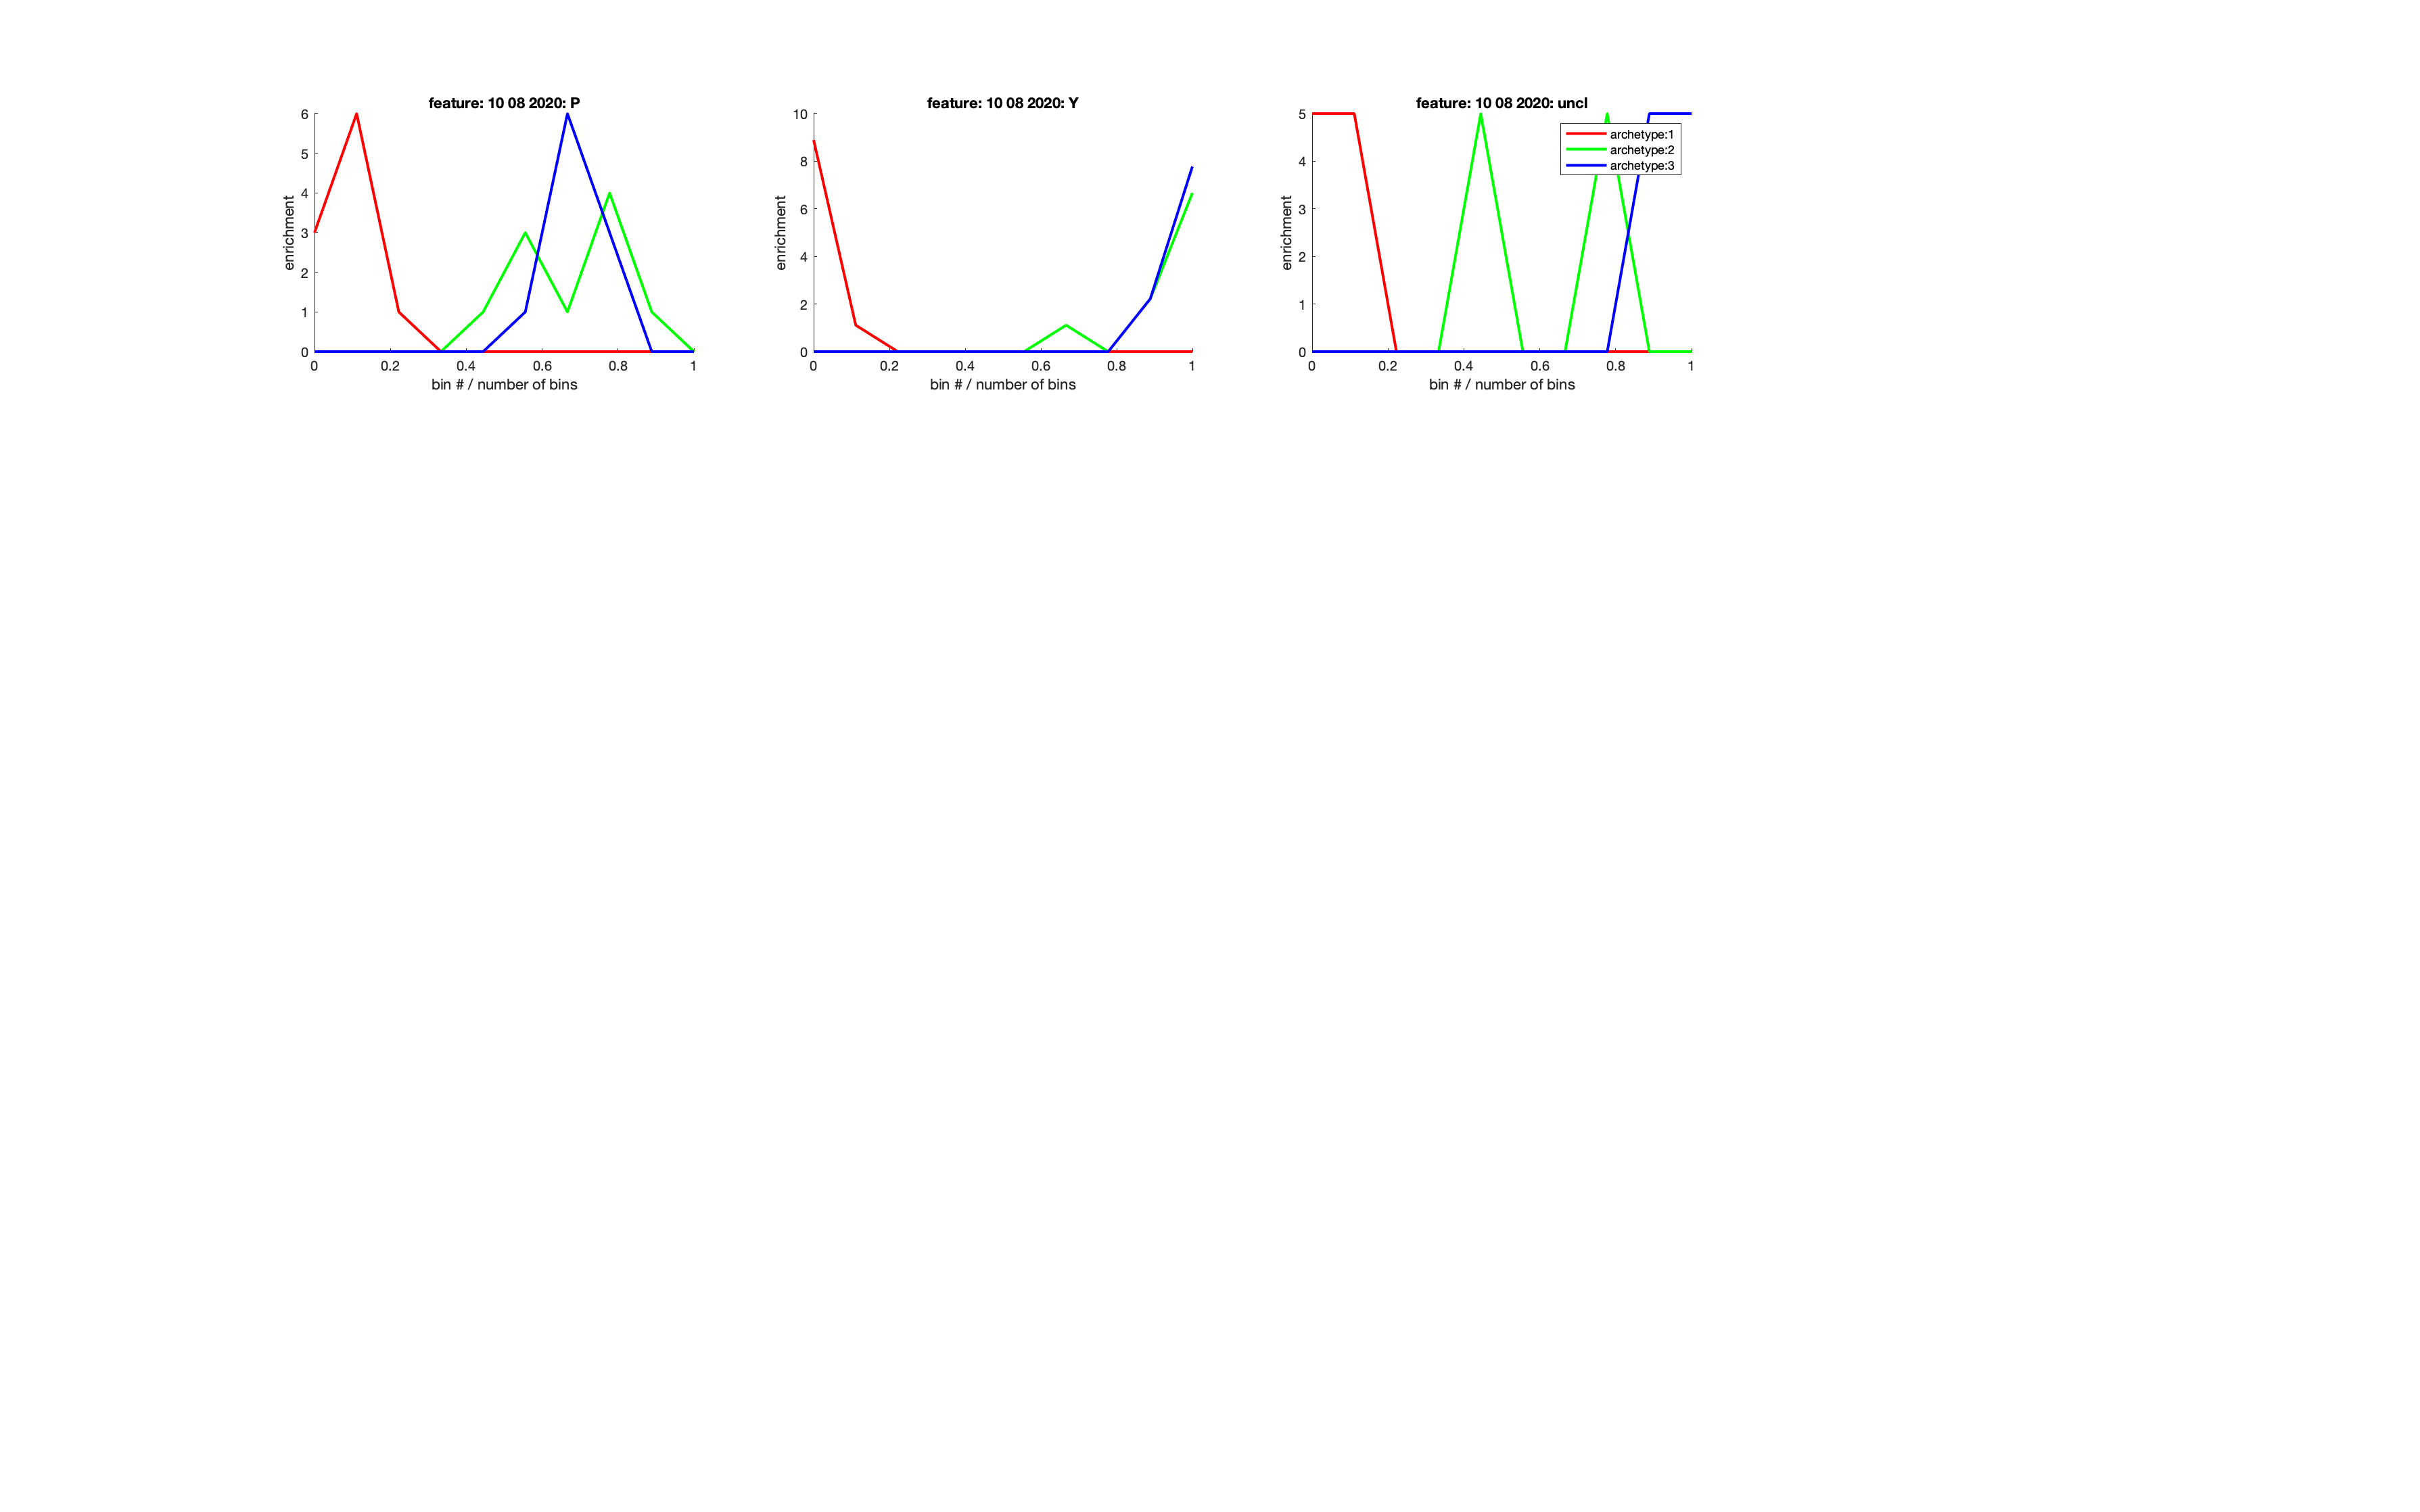

Finished computing discrete enrichments.
Finished computing continuous enrichments.
Now applying leave-one-out to verify robustness enrichment of GO categories
5% done
10% done
15% done
20% done
25% done
30% done
35% done
40% done
45% done
50% done
55% done
60% done
65% done
70% done
75% done
80% done
85% done
90% done
95% done
100% done
*** Wrote summary of enriched discrete features to /Users/smgroves/Documents/GitHub/Groves-CellSys2021/notebooks/ParTI-code/human-cell-lines/out/3/153473_discrete_significant.csv
*** Wrote summary of enriched continuous features to /Users/smgroves/Documents/GitHub/Groves-CellSys2021/notebooks/ParTI-code/human-cell-lines/out/3/153473_continuous_significant.csv
Starting to perform PCA, for big data on slow computers this may take a while...


Calculating explained variance with PCHA (Morup M, Hansen KL, 2011)


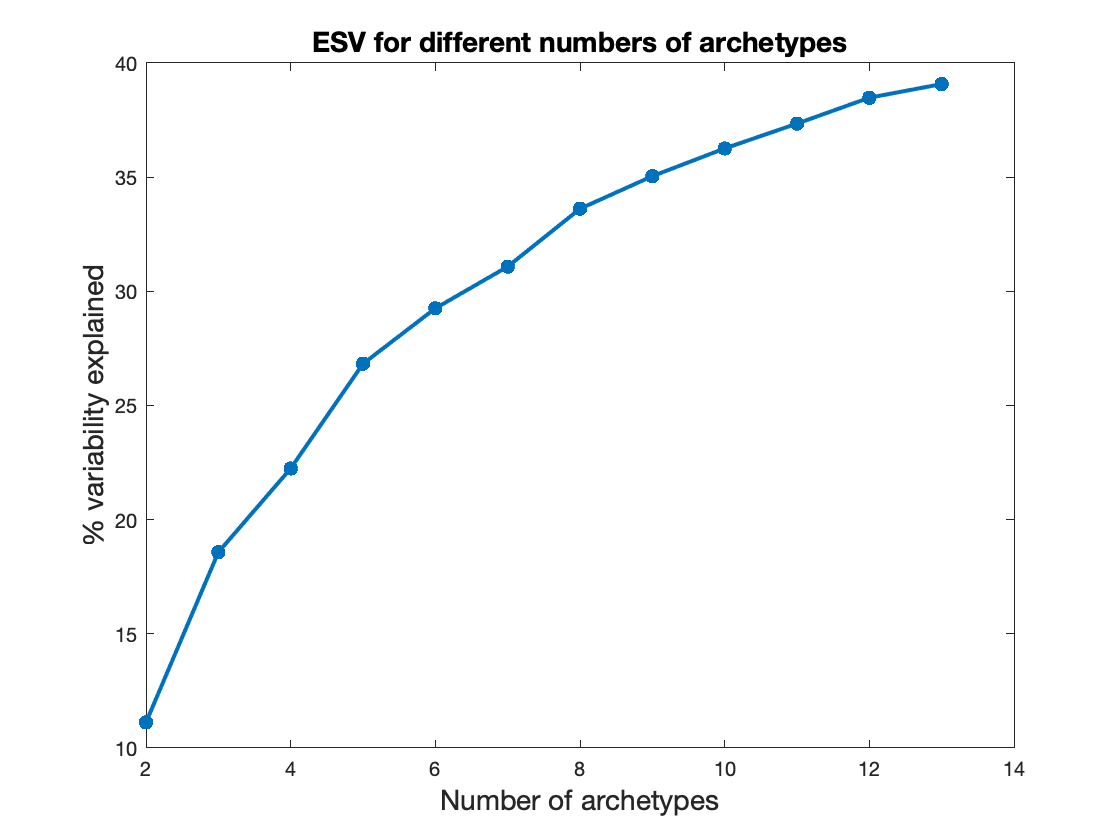

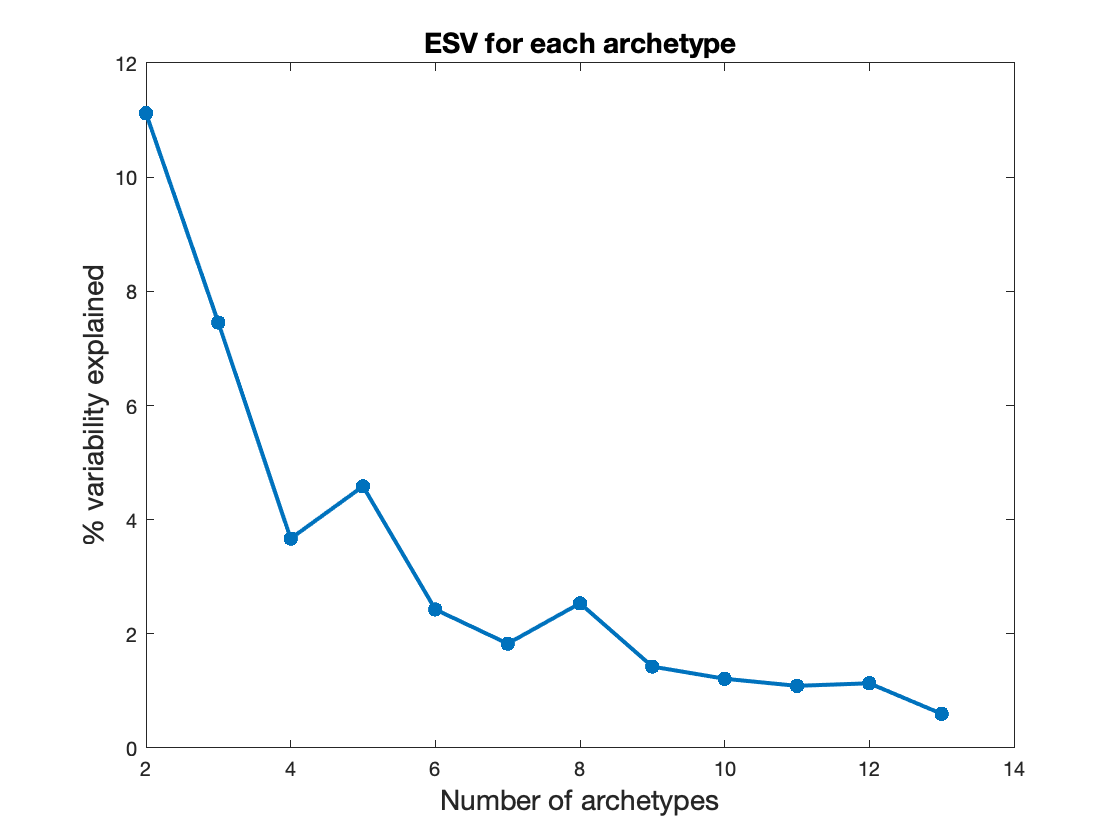

Warning! ForceNArchetypes preset in workspace to 7. Will now use that value.
Calculating archetypes positions with PCHA (Morup M & Hansen LK, 2011)
finished finding the archetypes
Now computing t-ratios.
10% done
20% done
30% done
40% done
50% done
60% done
70% done
80% done
90% done
100% done
The significance of 7 archetypes has p-value of: 0.00100 
Now calculating errors on the archetypes.
10% done
20% done
30% done
40% done
50% done
60% done
70% done
80% done
90% done
100% done
finished finding the archetypes error distribution


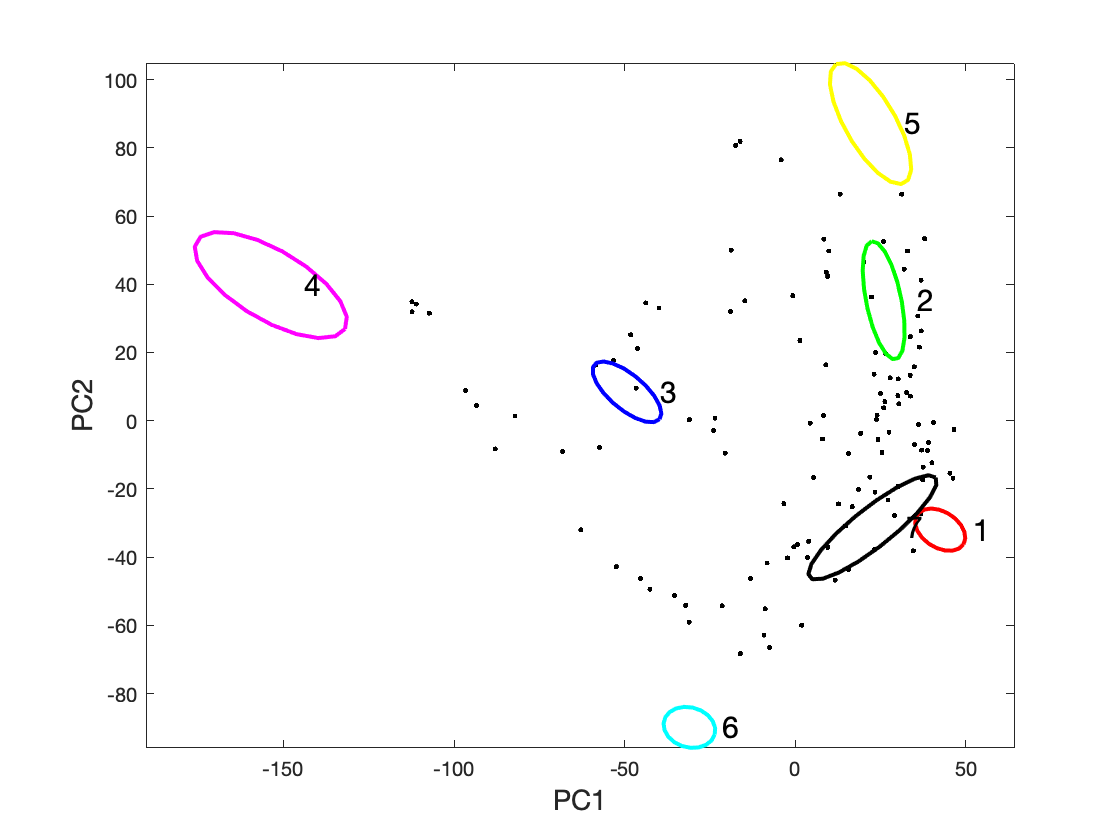

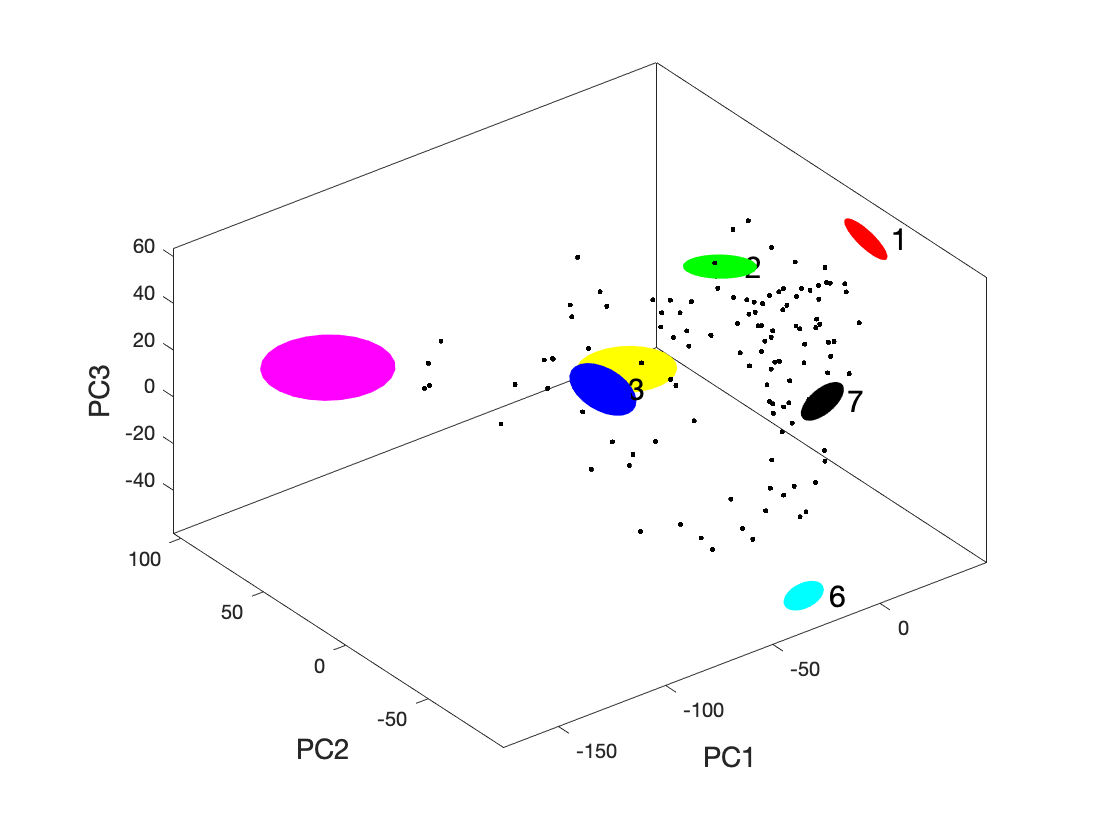

Finished sorting data points.
Your data was divided into 10 bins.


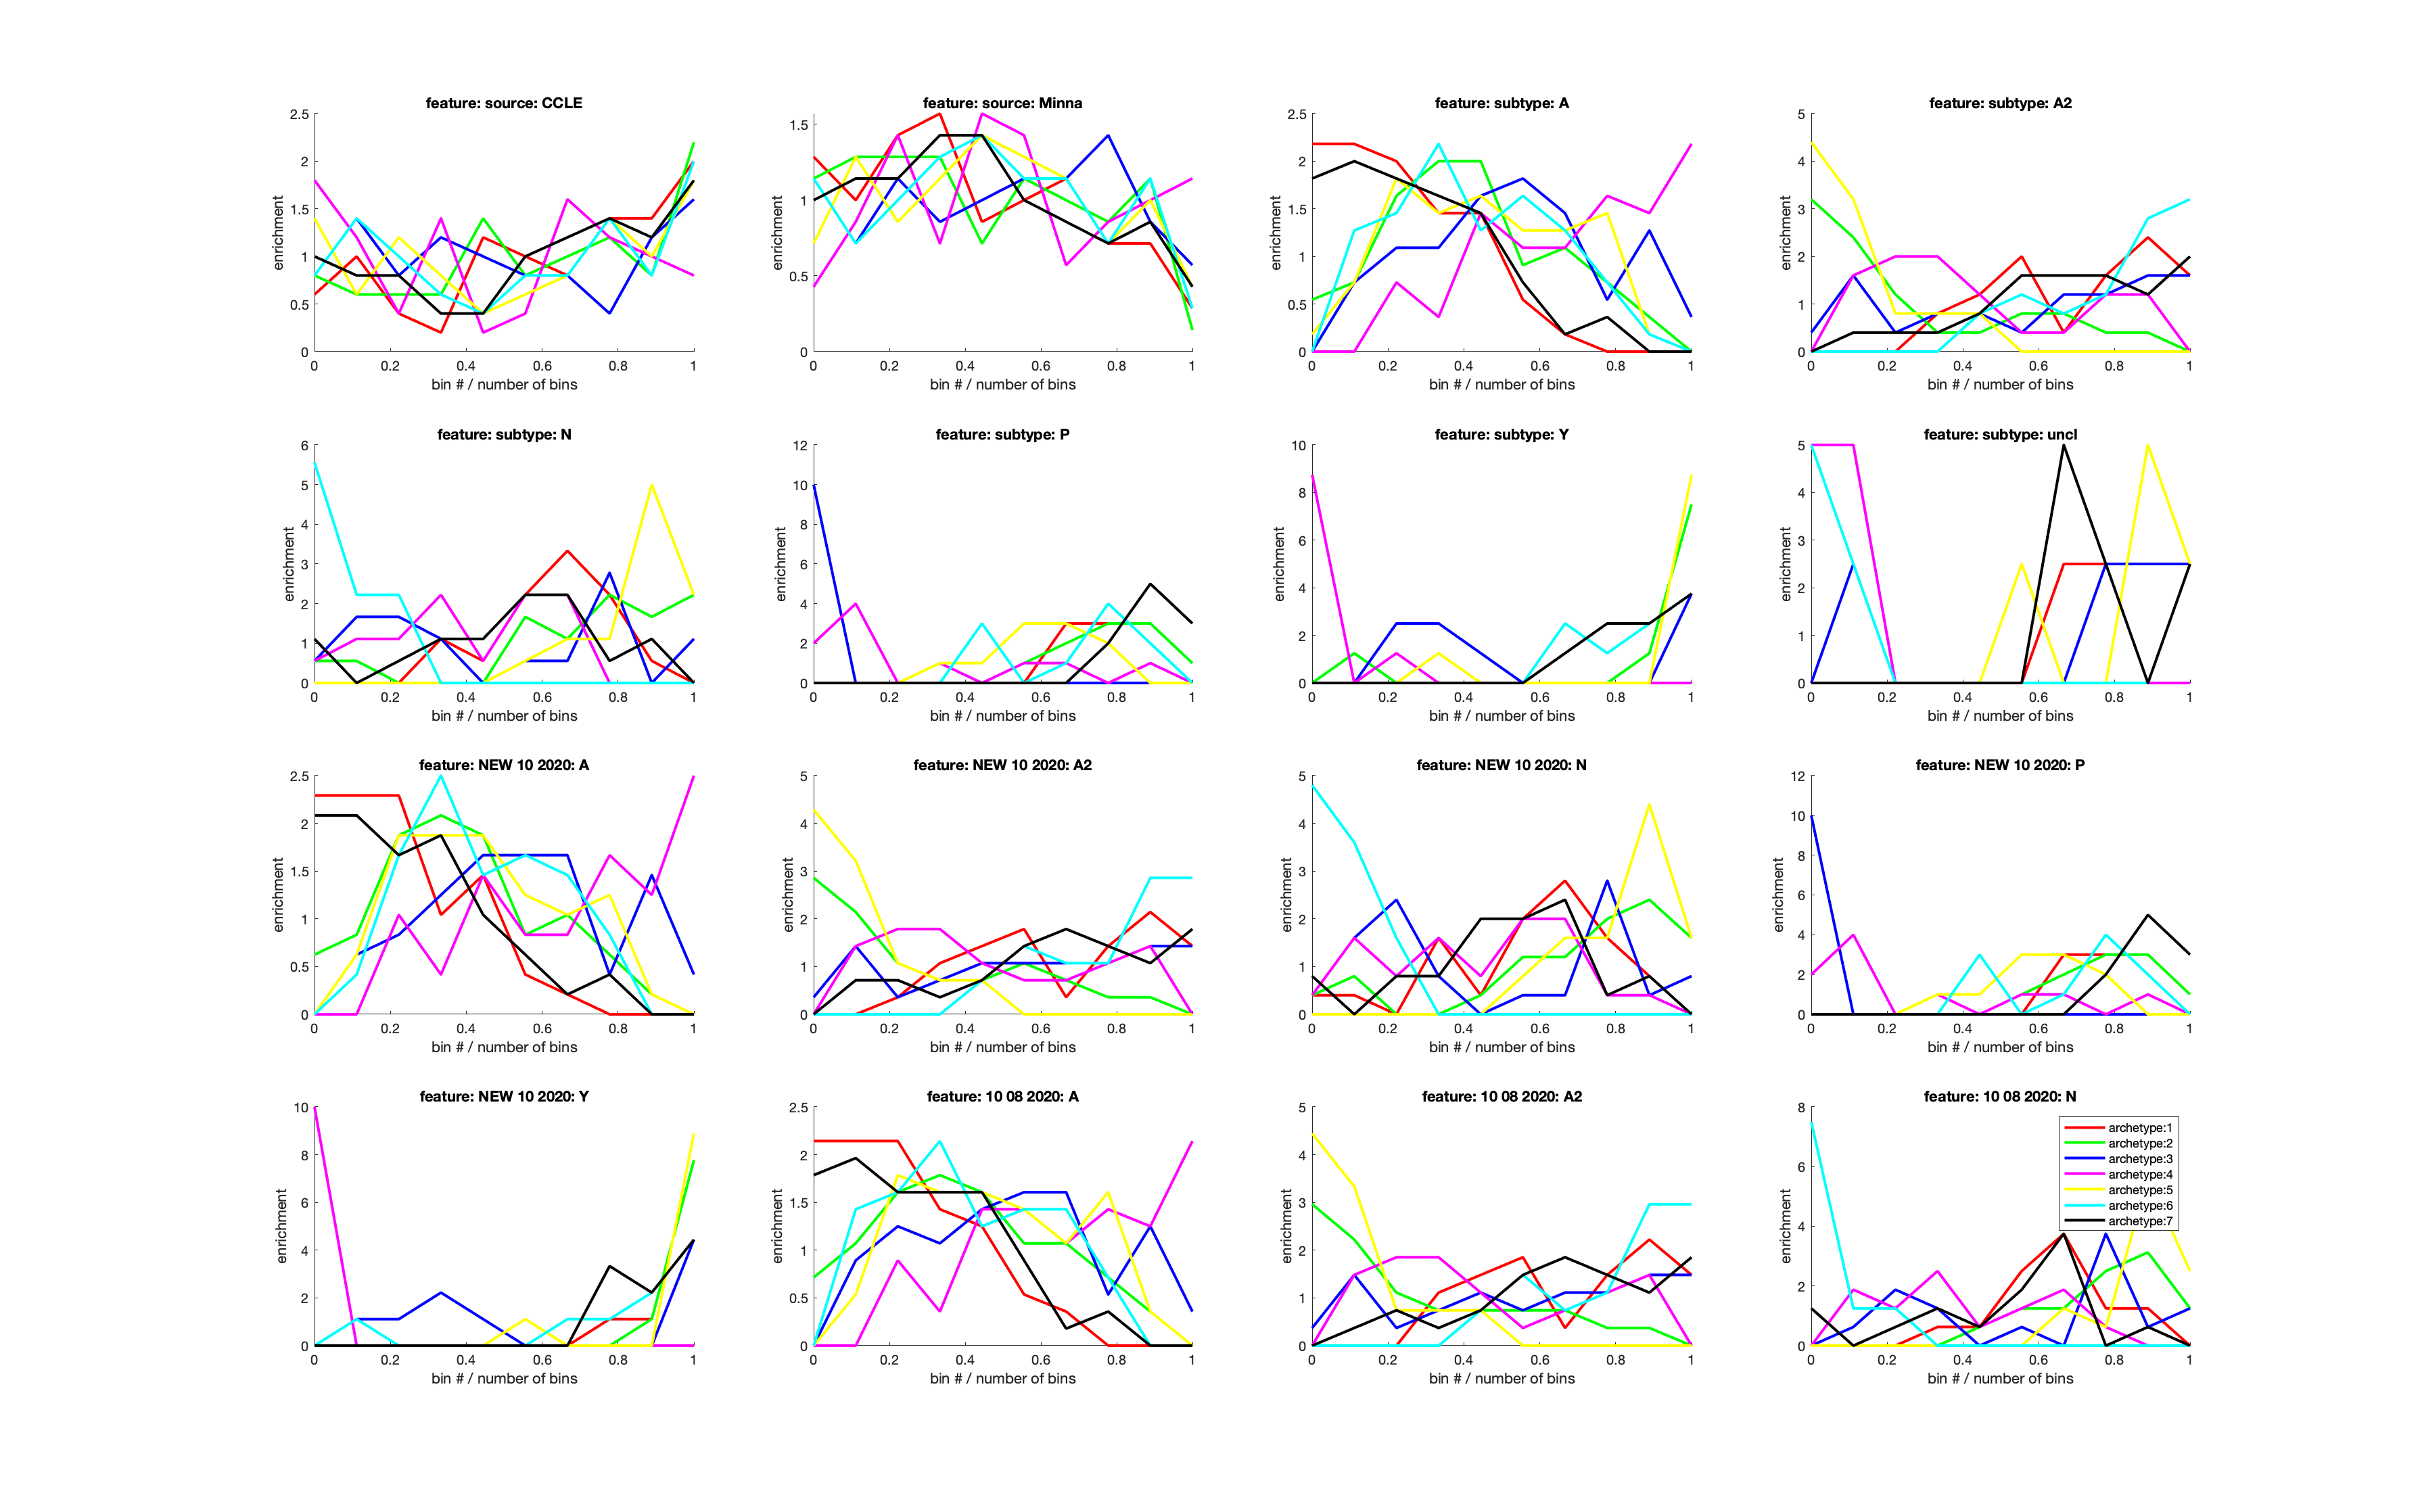

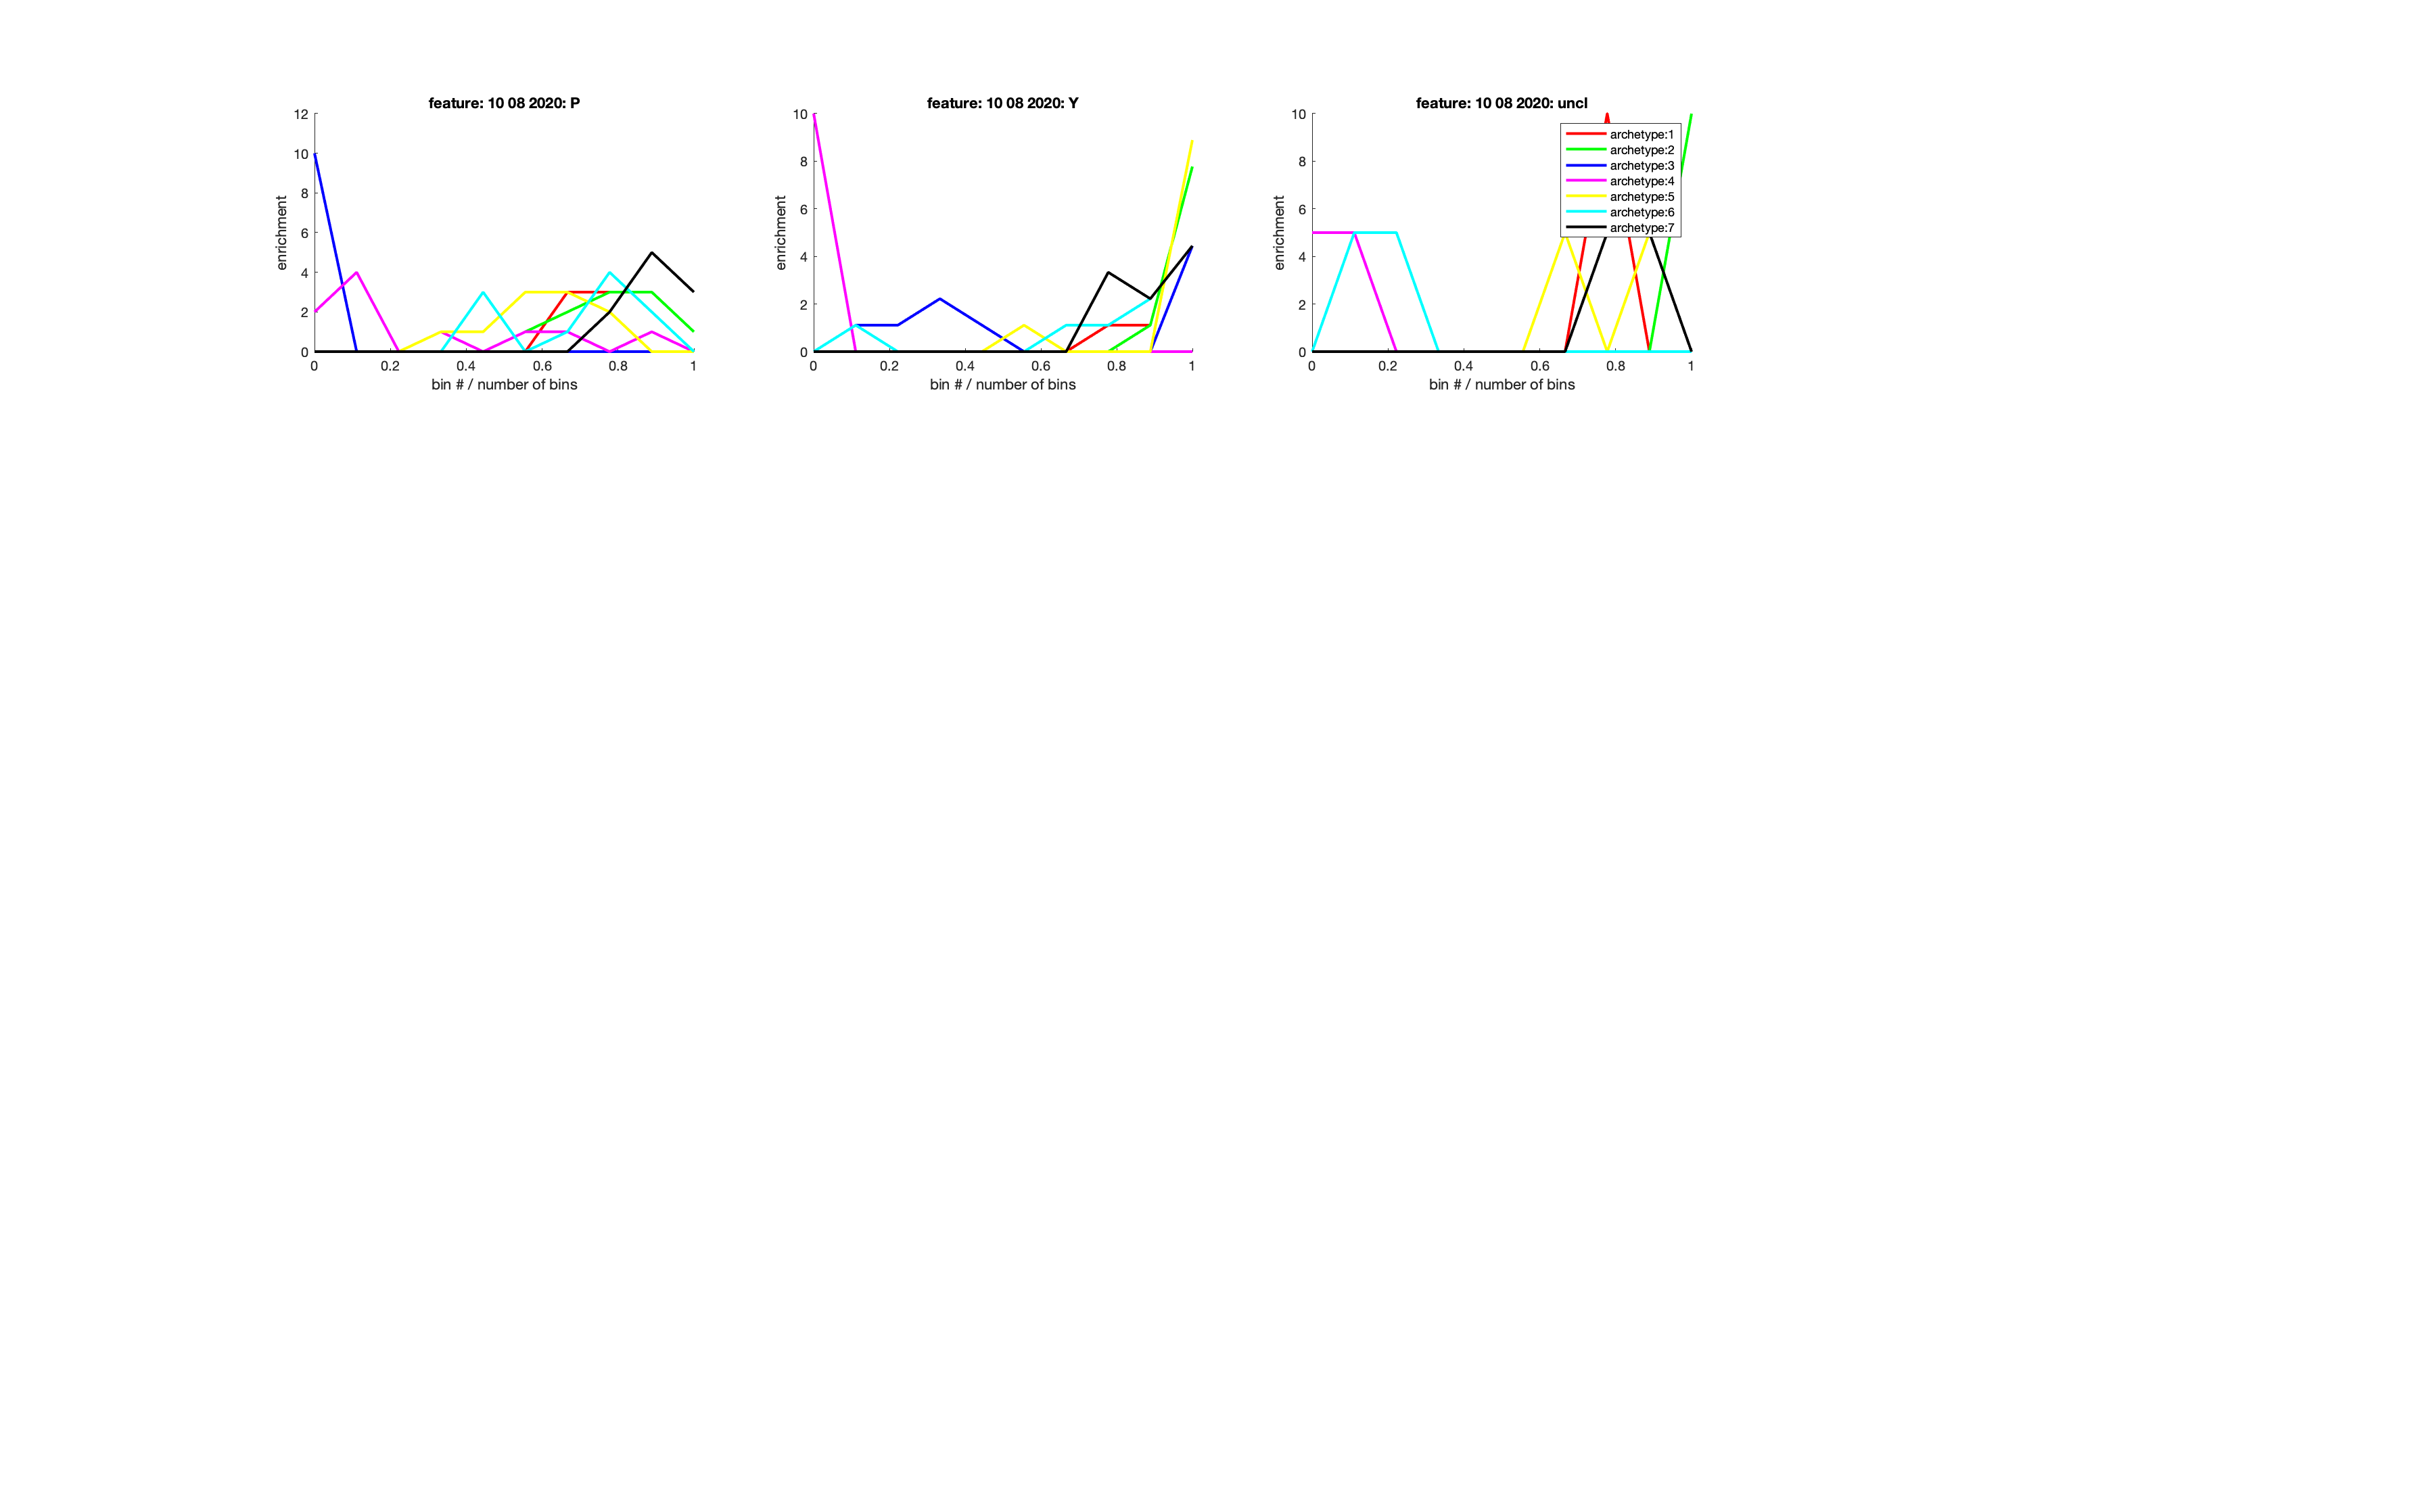

Finished computing discrete enrichments.
Finished computing continuous enrichments.
Now applying leave-one-out to verify robustness enrichment of GO categories
5% done
10% done


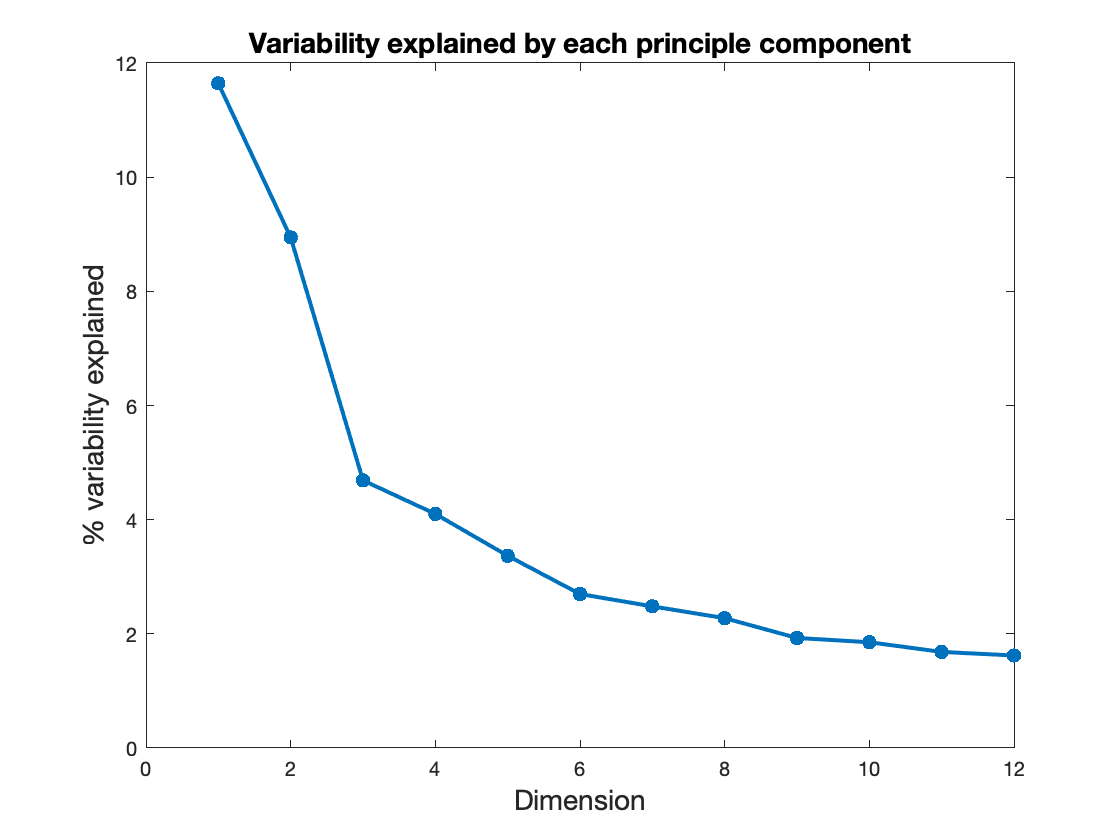

15% done
20% done
25% done
30% done
35% done
40% done
45% done
50% done
55% done
60% done
65% done
70% done
75% done
80% done
85% done
90% done
95% done
100% done
*** Wrote summary of enriched discrete features to /Users/smgroves/Documents/GitHub/Groves-CellSys2021/notebooks/ParTI-code/human-cell-lines/out/7/749365_discrete_significant.csv
*** Wrote summary of enriched continuous features to /Users/smgroves/Documents/GitHub/Groves-CellSys2021/notebooks/ParTI-code/human-cell-lines/out/7/749365_continuous_significant.csv



dim = 12;
binSize = 0.1 ;
for nArchetypes = [3 7]
    for algNum = [5]
        ForceNArchetypes = nArchetypes;
        random_int = randi(1000000);
        outputFileName = sprintf('%d',random_int);
        outPath = strcat(origPath, sprintf('/out/%d',nArchetypes));
        [arc, arcFull, pc, errs, pval, coefs, P, tRatioRand, tRatioReal] = ParTI(geneExpression, algNum, dim, discrAttrNames, ...
        discrAttr, 0, contAttrNames, contAttr,GOcat2Genes, binSize, strcat(outPath,'/', outputFileName));
        fid = fopen(strcat(origPath,'/params.txt'), 'a+');
        fprintf(fid, '%d, %d, %d, %d, %d,%d, %d\n', random_int,algNum,dim,binSize, nArchetypes, pval, tRatioReal);
        fclose(fid);
        csvwrite(strcat(outPath,sprintf('/%s_arc_full.csv',outputFileName)), arcFull);
        csvwrite(strcat(outPath,sprintf('/%s_errs.csv',outputFileName)), errs);
        csvwrite(strcat(outPath,sprintf('/%s_coefs.csv',outputFileName)), coefs);
        csvwrite(strcat(outPath,sprintf('/%s_tRatioRand.csv',outputFileName)), tRatioRand);
    
        clear arc arcFull pc errs pval coefs P tRatioRand tRatioReal
    end
end

### PCHA on Linear Scale Cell Line Data

% clear global ForceNArchetypes
% expGeneExpression = exp(geneExpression) - 1
% cd ../../../ParTI/

Starting to perform PCA, for big data on slow computers this may take a while...


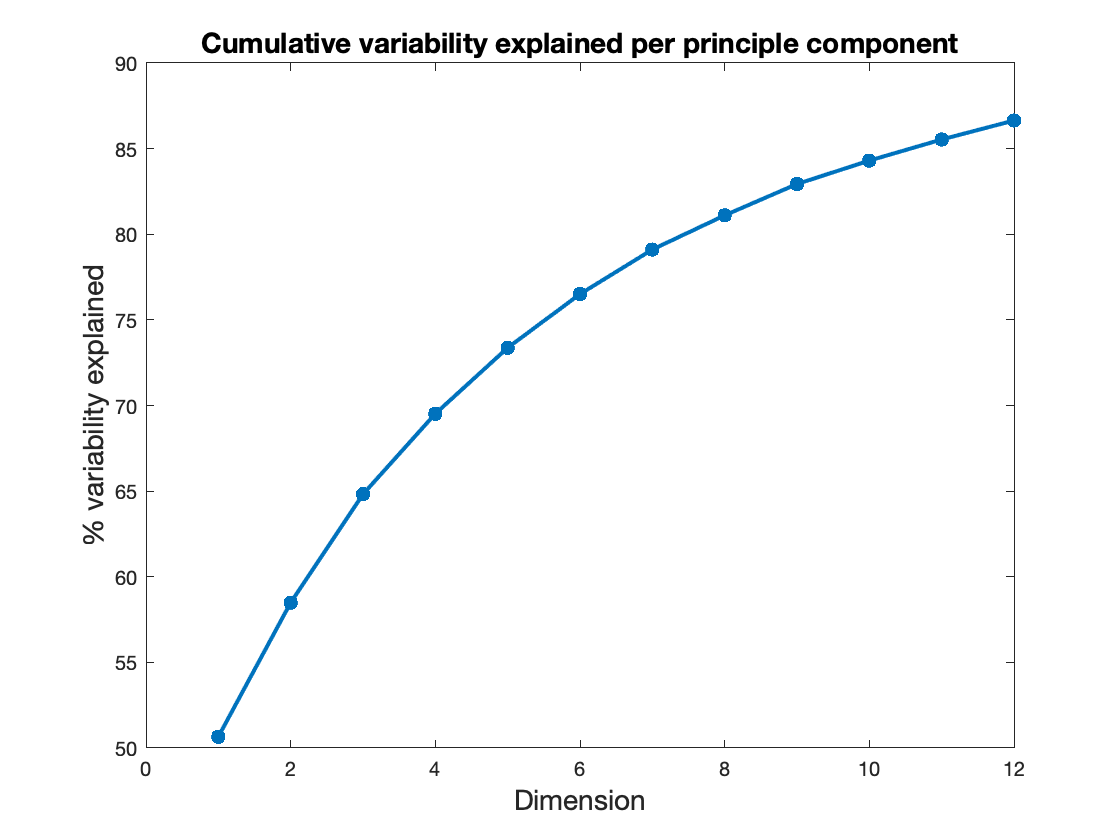

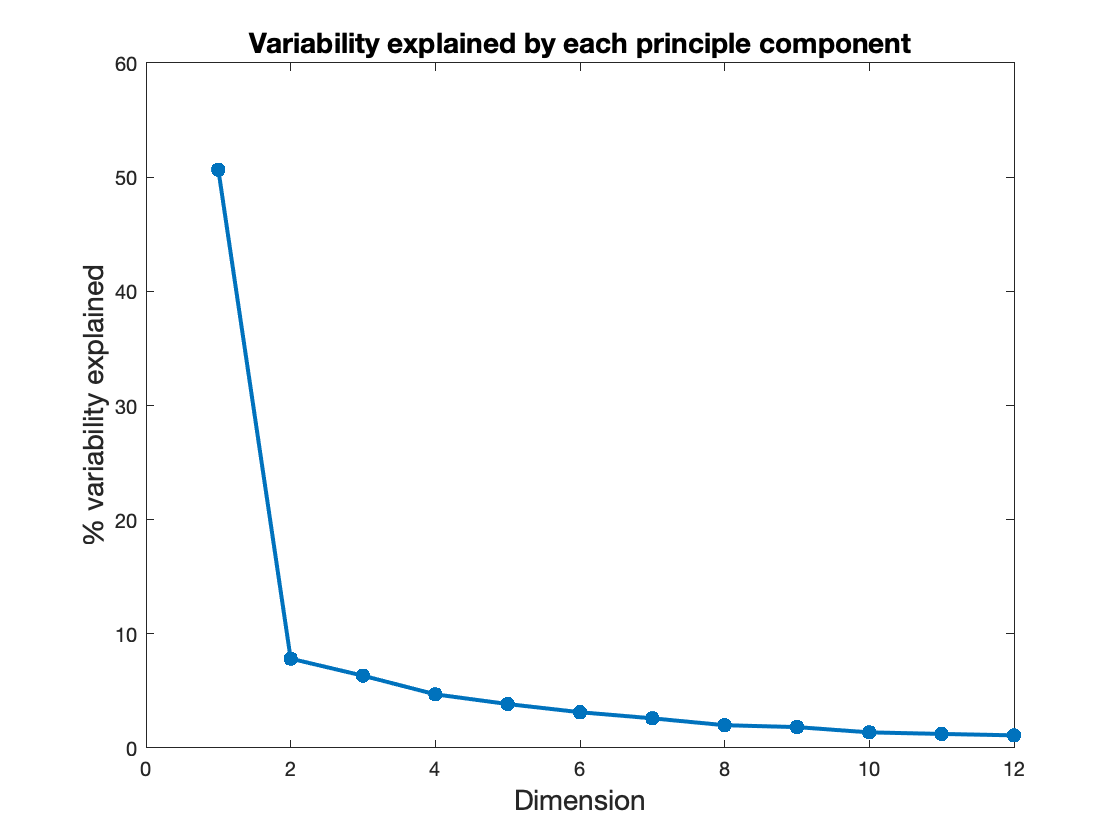

Calculating explained variance with PCHA (Morup M, Hansen KL, 2011)


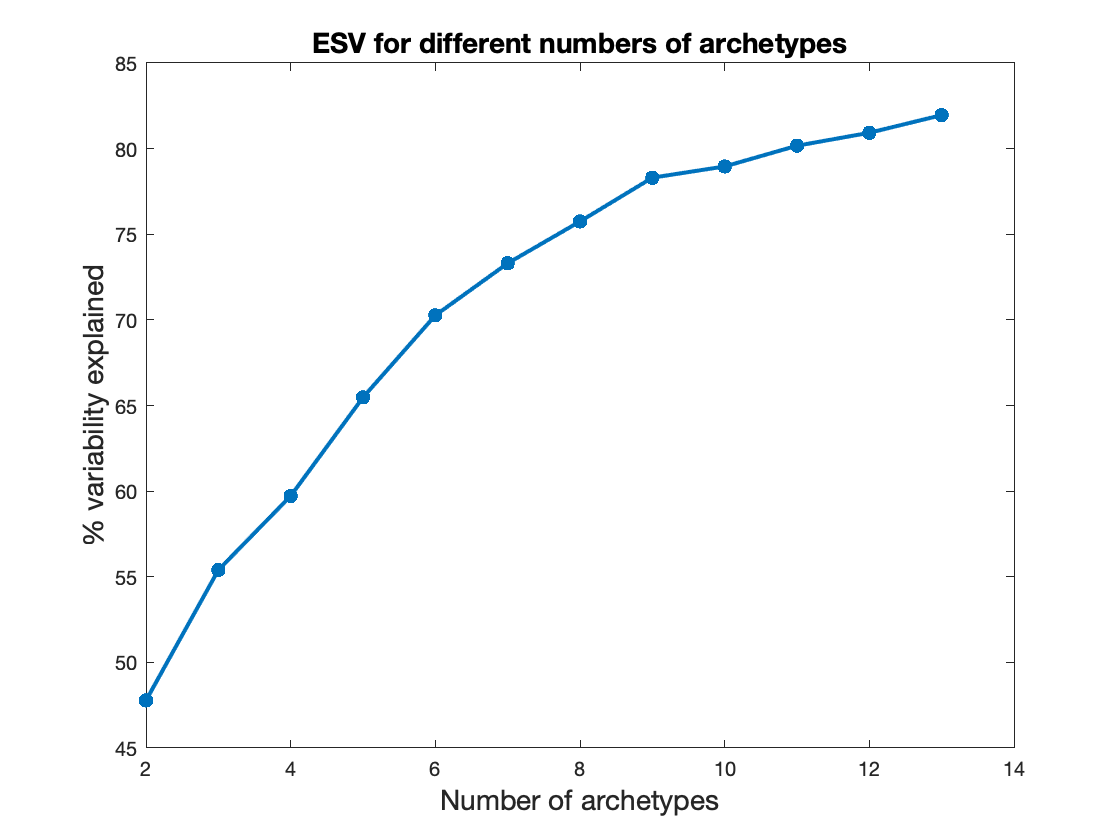

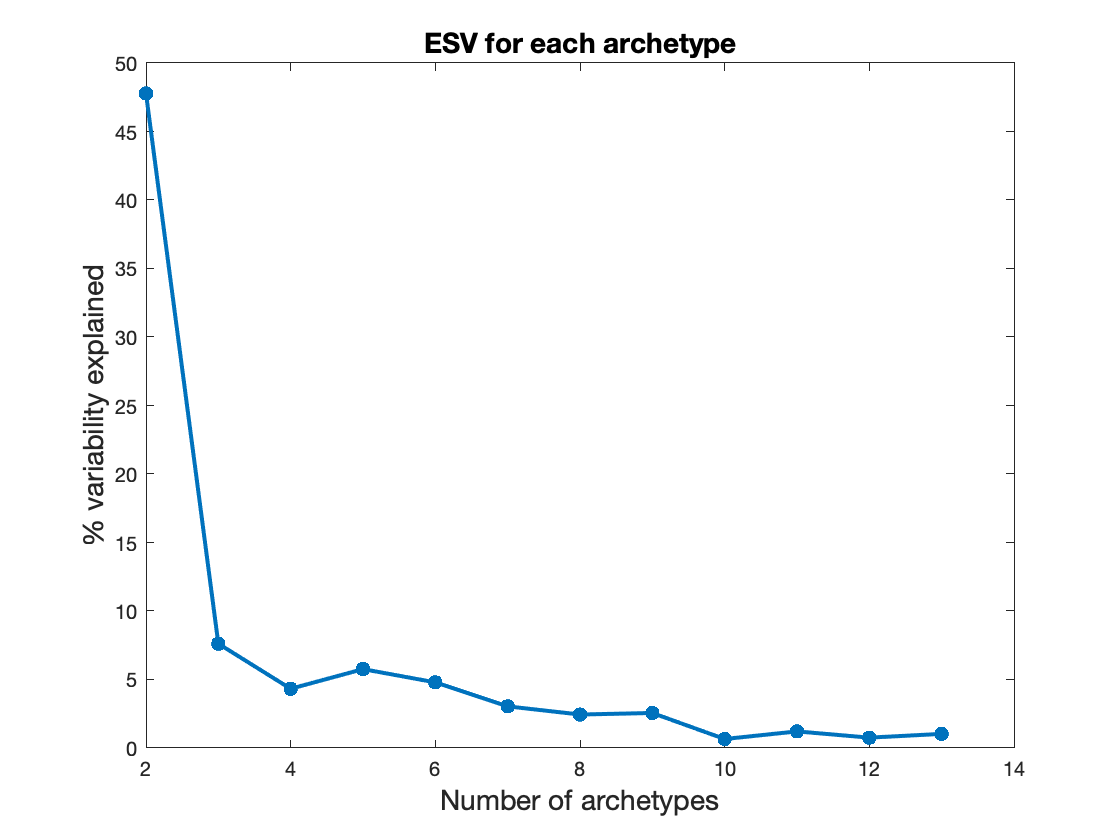

Warning! ForceNArchetypes preset in workspace to 3. Will now use that value.
Calculating archetypes positions with PCHA (Morup M & Hansen LK, 2011)
finished finding the archetypes
Now computing t-ratios.
10% done
20% done
30% done
40% done
50% done
60% done
70% done
80% done
90% done
100% done
The significance of 3 archetypes has p-value of: 0.90100 
Now calculating errors on the archetypes.
10% done
20% done
30% done
40% done


Error using save
Cannot create '105632_CumVarExpPCA.fig' because '/Users/smgroves/Documents/GitHub/Groves-CellSys2021/ParTI/out/3' does not exist.

Error in matlab.graphics.internal.figfile.FigFile/write (line 32)
save(obj.Path, obj.MatVersion, '-struct', 'SaveVars');

Error in <a href="matlab:matlab.internal.language.introspective.errorDocCallback('savefig', '/Applications/MATLAB_R2021a.app/toolbox/matlab/graphics/objectsystem/savefig.m', 83)" style="font-weight:bo

% [GOExpression,GONames,~,GOcat2Genes] = MakeGOMatrix(expGeneExpression, geneNames, ...
%                 {'MSigDB/c5.go.bp.v7.2.symbols.gmt'}, ...
%                 10);
% GOExpression is a matrix of patients x GO categories, and
% GONames contains the name of the GO categories.
% GOcat2Genes is a boolean matrix of genes x GO categories which
% indicates, for each category, which genes were used to compute it.
% In the next line, we expand this matrix so that it has as many columns as
% the number of continuous features (clinical + GO). Because clinical
% features are typically not directly based on specific genes, we add
% zeroes in the corresponding columns:
% GOcat2Genes=[zeros(size(GOcat2Genes,1),size(discrAttr,2)),GOcat2Genes];
% % and we expand the continuous clinical features with GO-based continuous
% % features:
% contAttrNames = [contAttrNames, GONames];
% contAttr = [contAttr, GOExpression];
contAttrNames = GONames;
contAttr = GOExpression;

for nArchetypes = [3 4 5 6 7]
    ForceNArchetypes = nArchetypes;
    random_int = randi(1000000);
    outputFileName = sprintf('%d',random_int);
    outPath = strcat(origPath, sprintf('/out/%d',nArchetypes));
    [arc, arcFull, pc, errs, pval, coefs, P, tRatioRand, tRatioReal] = ParTI(expGeneExpression, algNum, dim, discrAttrNames, ...
    discrAttr, 0, contAttrNames, contAttr,GOcat2Genes, binSize, strcat(outPath,'/', outputFileName));
    fid = fopen(strcat(origPath,'/params.txt'), 'a+');
    fprintf(fid, '%d, %d, %d, %d, %d,%d, %d\n', random_int,algNum,dim,binSize, nArchetypes, pval, tRatioReal);
    fclose(fid);
    csvwrite(strcat(outPath,sprintf('/%s_arc.csv',outputFileName)), arc);
    csvwrite(strcat(outPath,sprintf('/%s_pc.csv',outputFileName)), pc);

    csvwrite(strcat(outPath,sprintf('/%s_arc_full.csv',outputFileName)), arcFull);
    csvwrite(strcat(outPath,sprintf('/%s_errs.csv',outputFileName)), errs);
    csvwrite(strcat(outPath,sprintf('/%s_coefs.csv',outputFileName)), coefs);
    csvwrite(strcat(outPath,sprintf('/%s_tRatioRand.csv',outputFileName)), tRatioRand);

    clear arc arcFull pc errs pval coefs P tRatioRand tRatioReal
end


% dim = 20
% % for m=1:maxRuns
% % if mod(m,round(maxRuns/10)) == 0
% %     fprintf('%.0f%% done\n', 100*m/maxRuns);
% % end    
% %     if mod(m,10)==0
% %         disp(m);
% %     end
% SimplexRand1=zeros(size(geneExpression));
% % Shuffle the Sampled data -
% for i=1:size(geneExpression,2) % for each dimension
%     shuffInd=randperm(size(geneExpression,1)); % shuffle the data values of each axis
%     SimplexRand1(:,i)=geneExpression(shuffInd,i);
% end
% [coefsRand,scoresRand,variancesRand] = pca(SimplexRand1);
% percent_explainedRand = 100*cumsum(variancesRand)/sum(variancesRand);
% 
% % if exist('savefig')
% %     savefig([OutputFileName,'_CumVarExpPCA.fig']);
% % end
% [coefs1,scores1,variances] = pca(geneExpression);
% percent_explained = 100*cumsum(variances)/sum(variances);
% 
% figure;
% plot(1:dim,diff([0, percent_explained(1:dim)']),'.-','linewidth',2,'MarkerSize',20);
% plot(1:dim,diff([0, percent_explainedRand(1:dim)']),'.-','linewidth',2,'MarkerSize',20);
% 
% title('Variability explained by each principle component','fontsize',14);
% xlabel('Dimension','fontsize',14);ylabel('% variability explained','fontsize',14);
